clear,clc,format short g
n=10000;B=20;H=0.3;
nM=0.03;nMmin=0.027;nMmax=0.033;
S=0.0003;Smin=0.00027;Smax=0.00033;
Q=1./nM.*(B.*H).^(5/3)./(B+2*H).^(2/3).*sqrt(S)

Q =        1.5221

r=rand(n,1);
nMrand=nMmin+(nMmax-nMmin)*r;
Srand=Smin+(Smax-Smin)*r;
Qrand=1./nMrand.*(B.*H).^(5/3)./(B+2*H).^(2/3).*sqrt(Srand);
meanQ=mean(Qrand)

meanQ =        1.5241

Qmin=min(Qrand)

Qmin =        1.4513

Qmax=max(Qrand)

Qmax =        1.6044

DeltaQ=(max(Qrand)-min(Qrand))/meanQ/2*100.

DeltaQ =        5.0237

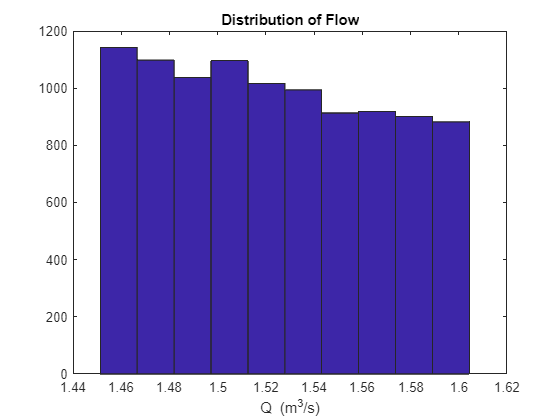

hist(Qrand),title('Distribution of Flow')
xlabel('Q (m^3/s)')